# Modelo robot movil

## Constantes

syms a b theta xp yp tp r t

%medidas
a = 11.78/2;
b = 9.13/2;
r = 1.19;
%Tiempo en el que se llegara al lugar [s]
T = 10;
%Posicione en cm
xi = 0;%x inicial
yi = 0;%y inicial
xf = 100;%x final
yf = 100;%y final
%Angulos en rad
ti = 0;%theta inicial
tf = pi;%theta final

%velocidades del robot
xp = (xf-xi)/T% [cm/s]

xp = 10

yp = (yf-yi)/T% [cm/s]

yp = 10

tp = (tf-ti)/T% [rad/s]

tp = 0.3142


theta = tp*t %El angulo dependera del tiempo

$$theta = \frac{\pi \,t}{10}$$


RZ = [cos(theta),-sin(theta),0;sin(theta),cos(theta),0;0,0,1]

$$RZ = \left(\begin{array}{ccc} \cos\left(\frac{\pi \,t}{10}\right) & -\sin\left(\frac{\pi \,t}{10}\right) & 0\\ \sin\left(\frac{\pi \,t}{10}\right) & \cos\left(\frac{\pi \,t}{10}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

EI = [xp;yp;tp]

EI =    10.0000
   10.0000
    0.3142


ER = RZ^(-1)*EI

$$ER = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\sigma_{2}\\ \sigma_{1}-\sigma_{2}\\ \frac{\pi }{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,\cos\left(\frac{\pi \,t}{10}\right)}{{\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}}\\ \sigma_{2}=\frac{10\,\sin\left(\frac{\pi \,t}{10}\right)}{{\cos\left(\frac{\pi \,t}{10}\right)}^{2}+{\sin\left(\frac{\pi \,t}{10}\right)}^{2}} \end{array}$$

%set L
L = sqrt(a*a+b*b)

L = 7.4519

%Set alphas
alpha1 = atan(b/a)

alpha1 = 0.6593

alpha2 = pi-alpha1

alpha2 = 2.4823

alpha3 = pi+alpha1

alpha3 = 3.8009

alpha4 = 2*pi-alpha1

alpha4 = 5.6238

alpha = [alpha1,alpha2,alpha3,alpha4]

alpha =     0.6593    2.4823    3.8009    5.6238


%Set betas
%90 - alpha + angulodeU1
beta1 = pi/2-alpha1

beta1 = 0.9115

beta2 = pi/2-alpha2

beta2 = -0.9115

beta3 = pi/2-alpha3+pi

beta3 = 0.9115

beta4 = pi/2-alpha4+pi

beta4 = -0.9115

beta = [beta1,beta2,beta3,beta4]

beta =     0.9115   -0.9115    0.9115   -0.9115


J = [sin(transpose(alpha+beta)),-cos(transpose(alpha+beta)),-L*cos(transpose(beta))]

J =     1.0000   -0.0000   -4.5650
    1.0000   -0.0000   -4.5650
   -1.0000    0.0000   -4.5650
   -1.0000    0.0000   -4.5650


phip = J*ER/r;
phip = vpa(simplify(phip),3)

$$phip = \left(\begin{array}{c} 8.4\,\cos\left(0.314\,t\right)+8.4\,\sin\left(0.314\,t\right)-1.21\\ 8.4\,\cos\left(0.314\,t\right)+8.4\,\sin\left(0.314\,t\right)-1.21\\ -8.4\,\cos\left(0.314\,t\right)-8.4\,\sin\left(0.314\,t\right)-1.21\\ -8.4\,\cos\left(0.314\,t\right)-8.4\,\sin\left(0.314\,t\right)-1.21 \end{array}\right)$$

V1 = phip(1)*r;
V3 = phip(3)*r;
VR = (V1+V3)/2;
X = vpa(VR*t*cos(theta),3)

Y = vpa(VR*t*sin(theta),3)

t = 0:0.1:T

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


X = eval(X)

X =          0   -0.1430   -0.1429   -0.1427   -0.1424   -0.1419   -0.1412   -0.1405   -0.1396   -0.1385   -0.1373   -0.1360   -0.1346   -0.1330   -0.1313   -0.1294   -0.1274   -0.1253   -0.1231   -0.1208   -0.1183   -0.1157   -0.1130   -0.1102   -0.1073   -0.1043   -0.1012   -0.0979   -0.0946   -0.0912   -0.0877   -0.0841   -0.0804   -0.0767   -0.0729   -0.0690   -0.0650   -0.0610   -0.0569   -0.0527   -0.0485   -0.0443   -0.0400   -0.0357   -0.0313   -0.0269   -0.0225   -0.0180   -0.0136   -0.0091


Y = eval(Y)

Y =          0         0   -0.0045   -0.0090   -0.0135   -0.0179   -0.0224   -0.0268   -0.0312   -0.0355   -0.0399   -0.0442   -0.0484   -0.0526   -0.0568   -0.0609   -0.0649   -0.0689   -0.0728   -0.0766   -0.0803   -0.0840   -0.0876   -0.0911   -0.0945   -0.0979   -0.1011   -0.1042   -0.1072   -0.1101   -0.1130   -0.1156   -0.1182   -0.1207   -0.1230   -0.1253   -0.1274   -0.1294   -0.1312   -0.1329   -0.1345   -0.1360   -0.1373   -0.1385   -0.1395   -0.1404   -0.1412   -0.1419   -0.1424   -0.1427


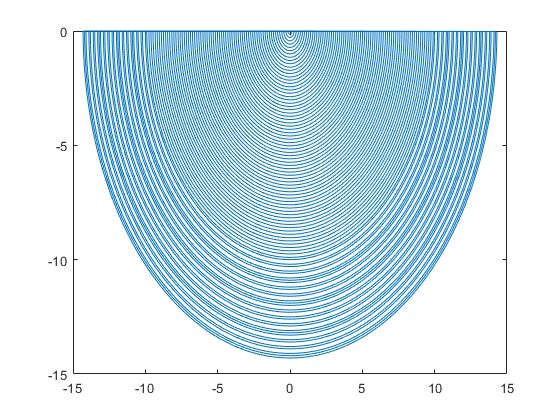

plot(X,Y)

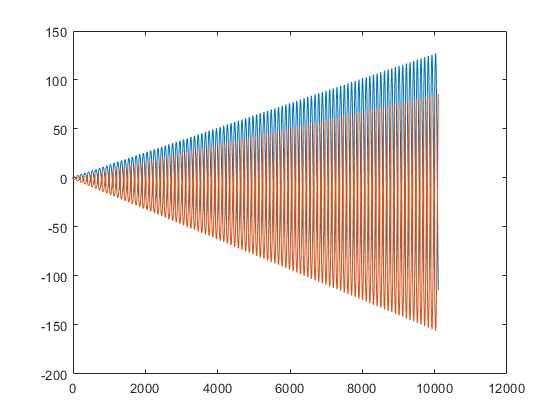

plot(eval(phip(1)*r*t))
hold on
plot(eval(phip(3)*r*t))
hold off